## Load Bbp data

cd('~/Documents/sedtrap_bbp');
bbp_dir = strcat(pwd, '/data_sbb');
cd(bbp_dir);
bbp_files = dir(fullfile(bbp_dir, 'bbp_*.tsv'));

% Initialize an empty table
bbp_tbl_raw = table();

% Loop through each file and append its contents
for i = 1:length(bbp_files)
    % --- Read the current TSV file ---
    % Create import options for a text file and specify the delimiter as a tab
    opts = detectImportOptions(bbp_files(i).name, 'FileType', 'text');
    opts.Delimiter = '\t'; % '\t' is the character for a tab
    
    % Read the table using these specific options
    tempTable = readtable(bbp_files(i).name, opts);
    
    % Append to the combined table
    bbp_tbl_raw = [bbp_tbl_raw; tempTable]; % Concatenation
end

bbp_tbl_raw  = sortrows(bbp_tbl_raw , 'datetime', 'ascend');
% Display the first 5 rows of the combined table
disp(bbp_tbl_raw (1:min(5, height(bbp_tbl_raw )), :));

          datetime          bbp_532nm      bbp_700nm 
    ____________________    __________    ___________

    26-Oct-2016 17:40:44       0.19479       0.084453
    26-Oct-2016 17:40:45       0.09762       0.040653
    26-Oct-2016 17:40:46    -0.0004111    -0.00022087
    26-Oct-2016 17:40:47      0.082257       0.027167
    26-Oct-2016 17:40:48       0.19479       0.076216



## Check for duplicate rows and clean data table

% Find all rows that are part of a duplicate set
% A row is a duplicate if its datetime matches the one AFTER it...
is_dup_with_next = [bbp_tbl_raw.datetime(1:end-1) == bbp_tbl_raw.datetime(2:end); false];

% ...OR if its datetime matches the one BEFORE it.
is_dup_with_prev = [false; bbp_tbl_raw.datetime(2:end) == bbp_tbl_raw.datetime(1:end-1)];

% Combine these two conditions. A row is a duplicate if either is true.
all_duplicate_mask = is_dup_with_next | is_dup_with_prev;

% Create the list of indices from the logical mask
duplicate_indices = find(all_duplicate_mask);

% Display the results
if ~isempty(duplicate_indices)
    fprintf('Found %d total rows that are part of a duplicate set.\n', numel(duplicate_indices));
    fprintf('The indices of these rows (in the sorted table) are:\n');
    
    % Display the indices as a row vector for easier reading
    disp(duplicate_indices'); 
    
    % Optional: To see the actual duplicate rows, you can uncomment the next line
    % disp(bbp_tbl_sorted(duplicate_indices, :));
else
    disp('No duplicate rows were found in the table.');
end

Found 107918 total rows that are part of a duplicate set.


The indices of these rows (in the sorted table) are:


  Columns 1 through 2730

         101         102         103         104         105         106         107         108         109         110         111         112         113         114         115         116         117         118         119         120         121         122         123         124         125         126         127         128         129         130         131         132         133         134         135         136         137         138         139         140         141         142         143         144         145         146         147         148         149         150         151         152         153         154         155         156         157         158         159         160         161         162         163         164         165         166         167         168         169         170         171         172         173         174         175         176         177         178         179         180         181  


% Find the indices of the first unique datetime entries
[~, unique_indices] = unique(bbp_tbl_raw.datetime);

% Create a new table containing only the unique rows
bbp_tbl_clean = bbp_tbl_raw(unique_indices, :);

fprintf('The table bbp_tbl_raw has %d rows.\n', height(bbp_tbl_raw));

The table bbp_tbl_raw has 237105 rows.


fprintf('The table bbp_tbl_clean has %d rows.\n', height(bbp_tbl_clean));

The table bbp_tbl_clean has 183146 rows.


## Plot Bbp data

range_bbp = [0 0.03]

range_bbp =          0    0.0300


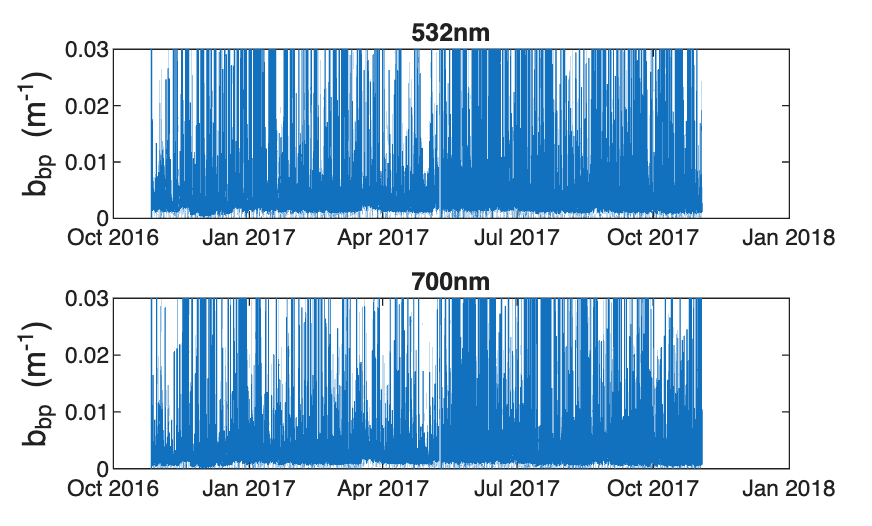


figure(1)
subplot(2,1,1)
    plot(bbp_tbl_clean {:,1},bbp_tbl_clean {:,2})
    title('532nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 
subplot(2,1,2)
    plot(bbp_tbl_clean {:,1},bbp_tbl_clean {:,3})
    title('700nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 

## Filter Bbp data

% Calculate the mean and standard deviation for bbp_532nm and bbp_700nm
mean532 = mean(bbp_tbl_clean .bbp_532nm);
std532 = std(bbp_tbl_clean .bbp_532nm);
mean700 = mean(bbp_tbl_clean .bbp_700nm);
std700 = std(bbp_tbl_clean .bbp_700nm);

filter_level = 5;

% Define the thresholds for filtering
upperThreshold532 = mean532 + filter_level * std532;
upperThreshold700 = mean700 + filter_level * std700;

% Filter out data points outside 3 standard deviations
bbp_tbl_532 = bbp_tbl_clean(bbp_tbl_clean.bbp_532nm <= upperThreshold532, :);
bbp_tbl_700 = bbp_tbl_clean(bbp_tbl_clean.bbp_700nm <= upperThreshold700, :);

% Display total number of rows in bbp_tbl_532
totalRows532 = height(bbp_tbl_532);
disp(['Total number of rows in bbp_tbl_532: ', num2str(totalRows532)]);

Total number of rows in bbp_tbl_532: 182232



% Display total number of rows in bbp_tbl_700
totalRows700 = height(bbp_tbl_700);
disp(['Total number of rows in bbp_tbl_700: ', num2str(totalRows700)]);

Total number of rows in bbp_tbl_700: 181980


## Smooth data

% Smooth input data
day_window = 30

day_window = 30

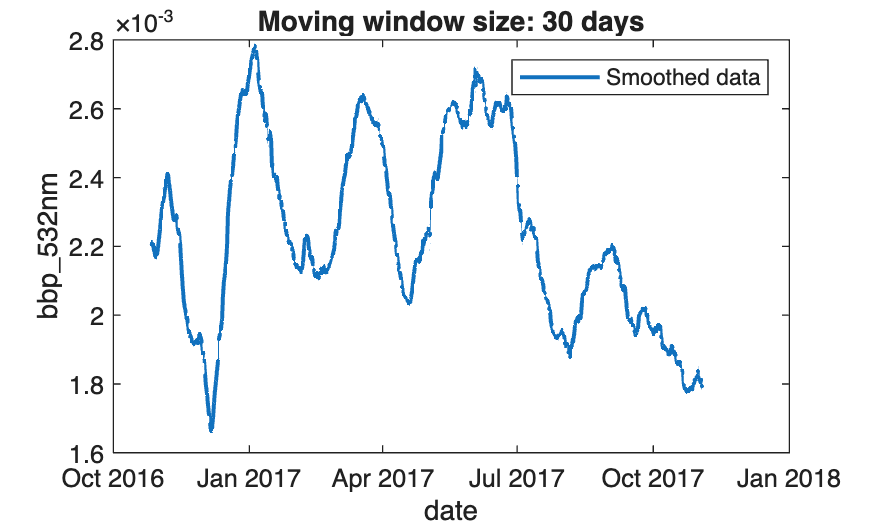

[smoothed532,winSize] = smoothdata(bbp_tbl_532(:,"bbp_532nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl_532.datetime);

% Display results
figure
plot(bbp_tbl_532.datetime,smoothed532.bbp_532nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize));
legend
ylabel("bbp_532nm",Interpreter="none")
xlabel("date")

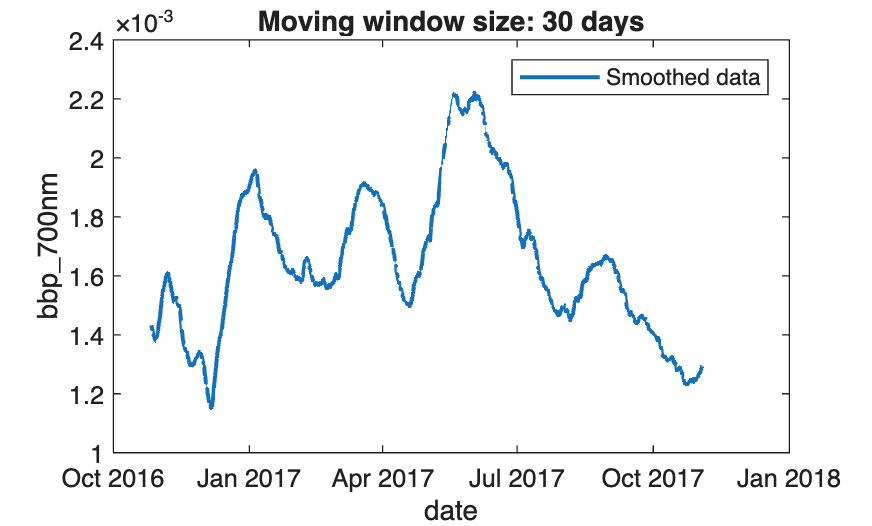


% Smooth input data
[smoothed700,winSize2] = smoothdata(bbp_tbl_700(:,"bbp_700nm"),"movmean",days(day_window), ...
    SamplePoints=bbp_tbl_700.datetime);

% Display results
figure
plot(bbp_tbl_700.datetime,smoothed700.bbp_700nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize2));
legend
ylabel("bbp_700nm",Interpreter="none")
xlabel("date")

clear winSize2

## Load and filter sediment trap data

trap_flux_tbl = readtable('trap_flux_sbb.csv');


% Exclude rows in trap_flux_tbl with Date values e.g. < 12/01/0022
% trap_flux_tbl(trap_flux_tbl.Mid_Date < datetime(2022, 12, 1), :) = [];

% Display the first 10 rows of the trap flux table
disp(trap_flux_tbl(1:min(10, height(trap_flux_tbl)), :));

    Cup    Duration       Date        Mid_Date     JulianDay    Mid_Julian    tot_mass_flux    org_c_flux    caco3_flux    opal_flux    terr_flux    nitro_flux
    ___    ________    __________    __________    _________    __________    _____________    __________    __________    _________    _________    __________

     1        15       2016-10-27    2016-11-03      8700         8707.5          1.881          0.097         0.177         0.324        1.137        0.011   
     2        15       2016-11-11    2016-11-18      8715         8722.5          2.352          0.094         

## Plot sediment trap data

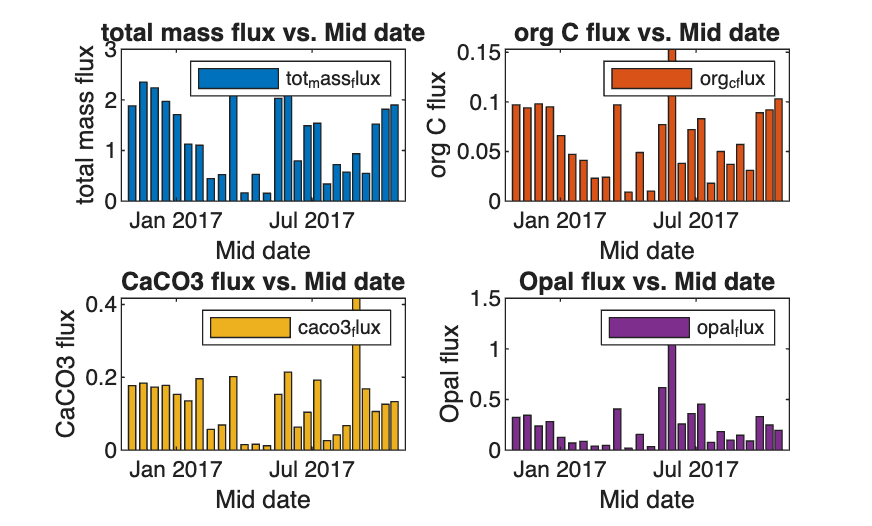

% Create a 2x2 subplot layout for the figures
figure

% Total Mass Flux
subplot(2,2,1)
h = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.tot_mass_flux, "DisplayName", "tot_mass_flux", 'FaceColor', [0 0.4470 0.7410]); % Blue
xlabel("Mid date")
ylabel("total mass flux")
title("total mass flux vs. Mid date")
legend

% Organic Carbon Flux
subplot(2,2,2)
h2 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.org_c_flux, "DisplayName", "org_c_flux", 'FaceColor', [0.8500 0.3250 0.0980]); % Red
xlabel("Mid date")
ylabel("org C flux")
title("org C flux vs. Mid date")
legend

% CaCO3 Flux
subplot(2,2,3)
h3 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.caco3_flux, "DisplayName", "caco3_flux", 'FaceColor', [0.9290 0.6940 0.1250]); % Yellow
xlabel("Mid date")
ylabel("CaCO3 flux")
title("CaCO3 flux vs. Mid date")
legend

% Opal Flux
subplot(2,2,4)
h4 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.opal_flux, "DisplayName", "opal_flux", 'FaceColor', [0.4940 0.1840 0.5560]); % Purple
xlabel("Mid date")
ylabel("Opal flux")
title("Opal flux vs. Mid date")
legend

## Overlay Bbp curves onto flux plots

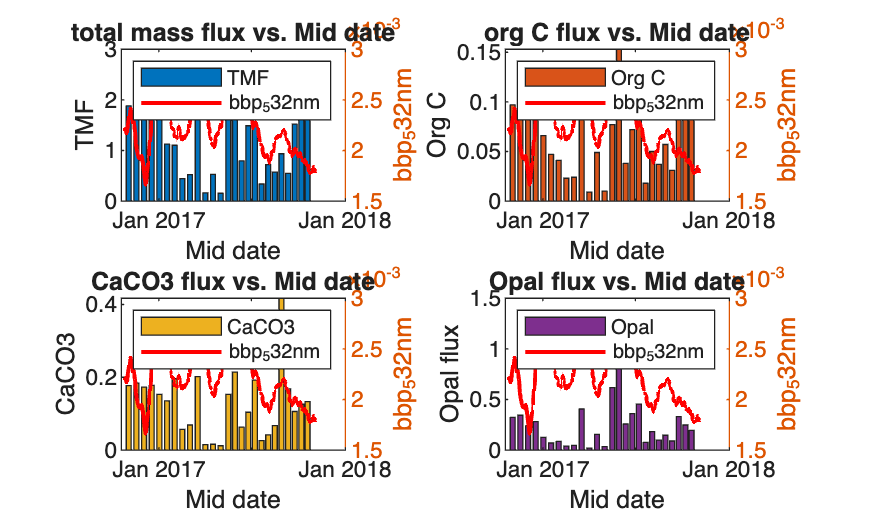

% Control variable selection for plotting
variableSelection = 'smoothed532'; % Change to 'smoothed532' or 'smoothed700' to select the other variable

% Create a 2x2 subplot layout for the figures
% Total Mass Flux
subplot(2,2,1)
yyaxis left
h5 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.tot_mass_flux, 'DisplayName', 'TMF', 'FaceColor', [0 0.4470 0.7410]); % Blue
ylabel('TMF')

yyaxis right
if strcmp(variableSelection, 'smoothed532')
    plot(bbp_tbl_532.datetime, smoothed532.bbp_532nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_532nm'); % Red
    ylabel('bbp_532nm')
else
    plot(bbp_tbl_700.datetime, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
    ylabel('bbp_700nm')
end
xlabel('Mid date')

% Organic Carbon Flux
subplot(2,2,2)
yyaxis left
h7 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.org_c_flux, 'DisplayName', 'Org C', 'FaceColor', [0.8500 0.3250 0.0980]); % Red
ylabel('Org C')

yyaxis right
if strcmp(variableSelection, 'smoothed532')
    plot(bbp_tbl_532.datetime, smoothed532.bbp_532nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_532nm'); % Red
    ylabel('bbp_532nm')
else
    plot(bbp_tbl_700.datetime, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
    ylabel('bbp_700nm')
end
xlabel('Mid date')

% CaCO3 Flux
subplot(2,2,3)
yyaxis left
h8 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.caco3_flux, 'DisplayName', 'CaCO3', 'FaceColor', [0.9290 0.6940 0.1250]); % Yellow
ylabel('CaCO3')

yyaxis right
if strcmp(variableSelection, 'smoothed532')
    plot(bbp_tbl_532.datetime, smoothed532.bbp_532nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_532nm'); % Red
    ylabel('bbp_532nm')
else
    plot(bbp_tbl_700.datetime, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
    ylabel('bbp_700nm')
end
xlabel('Mid date')

% Opal Flux
subplot(2,2,4)
yyaxis left
h6 = bar(trap_flux_tbl.Mid_Date, trap_flux_tbl.opal_flux, 'DisplayName', 'Opal', 'FaceColor', [0.4940 0.1840 0.5560]); % Purple
ylabel('Opal flux')

yyaxis right
if strcmp(variableSelection, 'smoothed532')
    plot(bbp_tbl_532.datetime, smoothed532.bbp_532nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_532nm'); % Red
    ylabel('bbp_532nm')
else
    plot(bbp_tbl_700.datetime, smoothed700.bbp_700nm, 'r-', 'LineWidth', 1.5, 'DisplayName', 'bbp_700nm'); % Red
    ylabel('bbp_700nm')
end
xlabel('Mid date')

## Calculate mean Bbp value for each cup cycle

% Initialize an empty table for results
if strcmp(variableSelection, 'smoothed532')
    avg_bbp_532_tbl = table();
end
if strcmp(variableSelection, 'smoothed700')
    avg_bbp_700_tbl = table();
end

% Loop through each row in trap_flux_tbl
for j = 1:height(trap_flux_tbl)
    % Define the date range
    startDate = trap_flux_tbl.Mid_Date(j);
    duration = trap_flux_tbl.Duration(j);
    endDate = startDate + duration;
    
    % Filter the selected smoothed data for the date range
    if strcmp(variableSelection, 'smoothed532')
        filteredData = smoothed532(bbp_tbl_532.datetime >= startDate & bbp_tbl_532.datetime < endDate, :);
    else
        filteredData = smoothed700(bbp_tbl_700.datetime >= startDate & bbp_tbl_700.datetime < endDate, :);
    end
    
    % Calculate the average bbp value
    if ~isempty(filteredData)
        if strcmp(variableSelection, 'smoothed532')
            avg_bbp = mean(filteredData.bbp_532nm);
            std_bbp = std(filteredData.bbp_532nm);
        else
            avg_bbp = mean(filteredData.bbp_700nm);
            std_bbp = std(filteredData.bbp_700nm);
        end
    else
        avg_bbp = NaN; % Assign NaN if no data is available
        std_bbp = NaN;
    end

    tmf = trap_flux_tbl.tot_mass_flux(j);
    ogc_c = trap_flux_tbl.org_c_flux(j);
    caco3 = trap_flux_tbl.caco3_flux(j);
    opal = trap_flux_tbl.opal_flux(j);
    
    % Append the results to the appropriate table
    if strcmp(variableSelection, 'smoothed532')
        avg_bbp_532_tbl = [avg_bbp_532_tbl; table(startDate, endDate, avg_bbp, std_bbp, tmf, ogc_c, caco3, opal)];
    else
        avg_bbp_700_tbl = [avg_bbp_700_tbl; table(startDate, endDate, avg_bbp, std_bbp, tmf, ogc_c, caco3, opal)];
    end
end

% Display the resulting table
if strcmp(variableSelection, 'smoothed532')
    disp(avg_bbp_532_tbl);
else
    disp(avg_bbp_700_tbl);
end

    startDate      endDate       avg_bbp      std_bbp       tmf     ogc_c    caco3    opal 
    __________    __________    _________    __________    _____    _____    _____    _____

    2016-11-03    2016-11-18    0.0022813    9.9876e-05    1.881    0.097    0.177    0.324
    2016-11-18    2016-12-03     0.001926    5.0431e-05    2.352    0.094    0.184    0.344
    2016-12-03    2016-12-18    0.0019005    0.00019029    2.238    0.098    0.173    0.238
    2016-12-18    2017-01-02    0.0025667    0.00011387     1.97    0.095    0.178    0.282
    2017-01-02    2017-01-17    0.0026348    0.00010486    1.707    0.066    0.153    0.126
    2017-01-17    2017-02-01    0.0022835    8.2776e-05    1.127    0.047    0.135 


% Filter out NaN values from the selected average bbp table
if strcmp(variableSelection, 'smoothed532')
    avg_bbp_532_tbl = rmmissing(avg_bbp_532_tbl);
else
    avg_bbp_700_tbl = rmmissing(avg_bbp_700_tbl);
end


## Create least-square regression

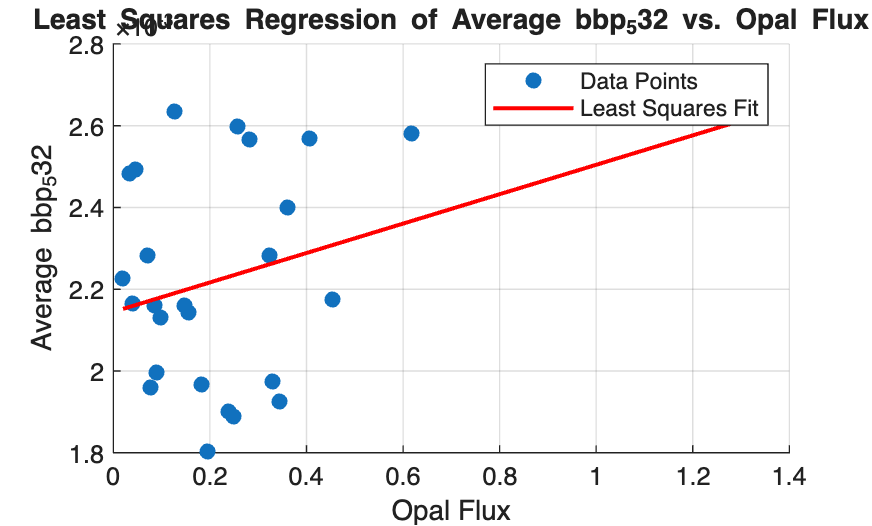

% Filter out NaN values from the selected average bbp table
if strcmp(variableSelection, 'smoothed532')
    avg_bbp_532_tbl = rmmissing(avg_bbp_532_tbl);
    
    % Perform least squares regression for smoothed532
    X = avg_bbp_532_tbl.opal(~isnan(avg_bbp_532_tbl.opal)); % Independent variable
    Y = avg_bbp_532_tbl.avg_bbp(~isnan(avg_bbp_532_tbl.opal)); % Dependent variable

    % Fit a linear model
    p = polyfit(X, Y, 1); % p(1) is the slope, p(2) is the intercept

    % Generate fitted values
    Y_fit = polyval(p, X);

    % Create a figure for the plot
    figure
    scatter(X, Y, 'filled', 'DisplayName', 'Data Points'); % Scatter plot of the data
    hold on
    plot(X, Y_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Least Squares Fit'); % Regression line
    hold off

    % Add labels and title
    xlabel('Opal Flux');
    ylabel('Average bbp_532');
    title('Least Squares Regression of Average bbp_532 vs. Opal Flux');
    legend('show');
    grid on;

else
    avg_bbp_700_tbl = rmmissing(avg_bbp_700_tbl);
    
    % Perform least squares regression for smoothed700
    X = avg_bbp_700_tbl.opal(~isnan(avg_bbp_700_tbl.opal)); % Independent variable
    Y = avg_bbp_700_tbl.avg_bbp(~isnan(avg_bbp_700_tbl.opal)); % Dependent variable

    % Fit a linear model
    p = polyfit(X, Y, 1); % p(1) is the slope, p(2) is the intercept

    % Generate fitted values
    Y_fit = polyval(p, X);

    % Create a figure for the plot
    figure
    scatter(X, Y, 'filled', 'DisplayName', 'Data Points'); % Scatter plot of the data
    hold on
    plot(X, Y_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Least Squares Fit'); % Regression line
    hold off

    % Add labels and title
    xlabel('Opal Flux');
    ylabel('Average bbp_700');
    title('Least Squares Regression of Average bbp_700 vs. Opal Flux');
    legend('show');
    grid on;
end